lut = readtable('COMP NEURO BIDS\BN_Atlas_246_LUT.txt')

lut = 247×6 table
    Var1        Var2        Var3    Var4    Var5    Var6
    ____    ____________    ____    ____    ____    ____

      0     {'Unknown' }     25       5      25      0  
      1     {'A8m_L'   }      0     255       0      0  
      2     {'A8m_R'   }      0       0     255      0  
      3     {'A8dl_L'  }    255       0       0      0  
      4     {'A8dl_R'  }      0     246     255      0  
      5     {'A9l_L'   }    255     123     220      0  
      6     {'A9l_R'   }    255     220     123      0  
      7     {'A6dl_L'  }      0     141     255      0  
      8     {'A6dl_R'  }      0     106       9      0  
      9     {'A6m_L'   }    158      70      53      0  
     10     {'A6m_R'   }     62       0     106      0  
     11     {'A9m_L'   }    255     


info = niftiinfo('COMP NEURO BIDS/BN_Atlas_246_1mm.nii');
raw_atlas = niftiread(info);

atlas = double(raw_atlas) * info.MultiplicativeScaling + info.AdditiveOffset;

unique(atlas(:))

ans =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14


insula_indices = 165:174

insula_indices =    165   166   167   168   169   170   171   172   173   174


insula_mask = ismember(atlas, insula_indices);

datafolder = ('C:\Users\madis\Documents\COMP NEURO BIDS')

datafolder = 'C:\Users\madis\Documents\COMP NEURO BIDS'


participant_ids = [1,2,3,4,5,6,7,8,14,18,31,34,39,43,50,52,53,57,58,63,64,67,71,74,75,76,81,88,102,106,109,115,119,122,130,136,139,149,154,156,158,159,167,169,179,180,187,191,192,193,194,195,196,197]

participant_ids =      1     2     3     4     5     6     7     8    14    18    31    34    39    43    50    52    53    57    58    63    64    67    71    74    75    76    81    88   102   106   109   115   119   122   130   136   139   149   154   156   158   159   167   169   179   180   187   191   192   193


runs = 2;
insula_values = zeros(length(participant_ids), 1);

for positionnmbr = 1:length(participant_ids)
    sub_id = participant_ids(positionnmbr);
    run_values = zeros(runs,1);

    for r = 1:runs
        brainfile = fullfile(datafolder, ...
            sprintf('sub-%03d', sub_id), 'func', ...
            sprintf('sub-%03d_task-empathy_acq-MNI152NLin6Asym_rec-preproc_run-%02d_bold.nii', sub_id, r));
        braininfo = (niftiinfo(brainfile));
        brain_activity = double(niftiread(braininfo));
        insula_voxels = brain_activity(insula_mask);
        run_values(r) = mean(insula_voxels);
    end
    insula_values(positionnmbr) = mean(run_values);

end

disp(insula_values)

   1.0e+04 *

   -2.8190
   -2.7499
   -2.6443
   -2.7001
   -2.7882
   -2.6858
   -2.7379
   -2.6263
   -2.7015
   -2.7016
   -2.7827
   -2.7268
   -2.7828
   -2.7851
   -2.8036
   -2.8756
   -2.6853
   -2.7398
   -2.7780
   -2.6717
   -2.6049
   -2.6814
   -2.6842
   -2.6766
   -2.6144
   -2.5480
   -2.5483
   -2.8806
   -2.7142
   -2.7936
   -2.7239
   -2.5870
   -2.8487
   -2.6058
   -2.7044
   -2.7778
   -2.6154
   -2.8397
   -2.8352
   -2.6384
   -2.6736
   -2.8207
   -2.8007
   -2.7357
   -2.6001
   -2.6883
   -2.6629
   -2.7172
   -2.7017
   -2.8657
   -2.6527
   -2.7696
   -2.6678
   -2.8225



summary(insula_values)


insula_values: 54×1 double

    NumMissing                0  
    Min             -2.8806e+04  
    Median          -2.7093e+04  
    Max             -2.5480e+04  
    Mean            -2.7201e+04  
    Std                844.5783  



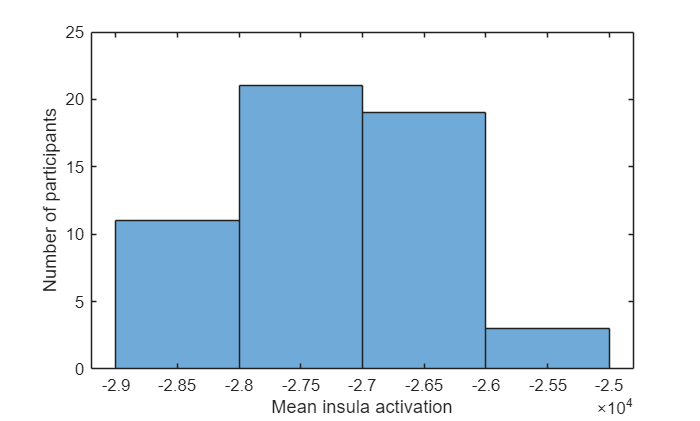

histogram(insula_values)
xlabel('Mean insula activation')
ylabel('Number of participants')

n = 54;
meanTEQ = 46.25;
sdTEQ = 7.55;
empathy = round(min(max(meanTEQ + sdTEQ * randn (54,1),0),64))

empathy =     49
    54
    54
    41
    48
    39
    36
    53
    46
    46
    53
    51
    49
    56
    53


summary(empathy)


empathy: 54×1 double

    NumMissing            0  
    Min                  27  
    Median               47  
    Max                  56  
    Mean            45.6481  
    Std              7.4433  



brain_activity = insula_values

brain_activity = 1.0e+04 *

   -2.8190
   -2.7499
   -2.6443
   -2.7001
   -2.7882
   -2.6858
   -2.7379
   -2.6263
   -2.7015
   -2.7016
   -2.7827
   -2.7268
   -2.7828
   -2.7851
   -2.8036


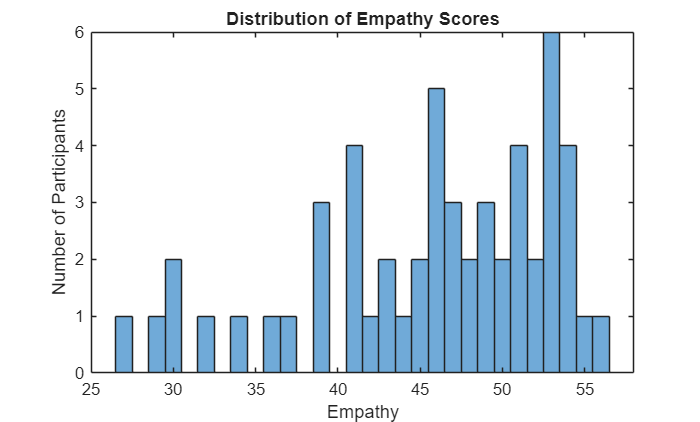


histogram(empathy)
xlabel('Empathy')
ylabel('Number of Participants')
title ('Distribution of Empathy Scores')

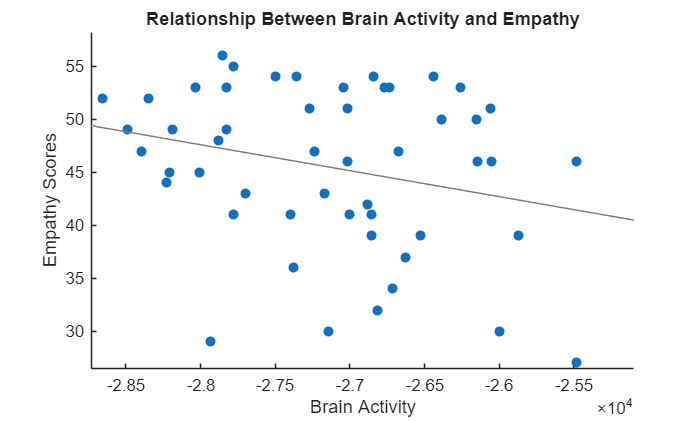


scatter(brain_activity, empathy, "filled")
xlabel('Brain Activity')
ylabel('Empathy Scores')
title('Relationship Between Brain Activity and Empathy')
lsline


model = fitlm(brain_activity, empathy)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat       pValue 
                   __________    _________    ________    ________

    (Intercept)       -21.046       31.947    -0.65878     0.51295
    x1             -0.0024519    0.0011739     -2.0887    0.041652


Number of observations: 54, Error degrees of freedom: 52
Root Mean Squared Error: 7.22
R-squared: 0.0774,  Adjusted R-Squared: 0.0597
F-statistic vs. constant model: 4.36, p-value = 0.0417

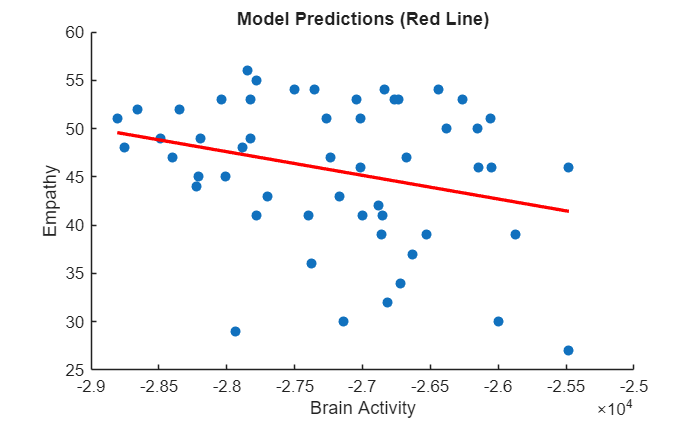


predicted_empathy = predict(model, brain_activity);

scatter(brain_activity, empathy, "filled")
hold on
plot(brain_activity, predicted_empathy, 'r', 'LineWidth', 2)
hold off
xlabel('Brain Activity')
ylabel('Empathy')
title('Model Predictions (Red Line)')

n = 54;
meanTEQ = 45;
sdTEQ = 7; 
empathy = round(min(max(meanTEQ + sdTEQ * randn(54,1),0),64))

empathy =     32
    52
    62
    52
    43
    48
    38
    58
    52
    51
    39
    47
    41
    43
    41


brain_activity = insula_values

brain_activity = 1.0e+04 *

   -2.8190
   -2.7499
   -2.6443
   -2.7001
   -2.7882
   -2.6858
   -2.7379
   -2.6263
   -2.7015
   -2.7016
   -2.7827
   -2.7268
   -2.7828
   -2.7851
   -2.8036


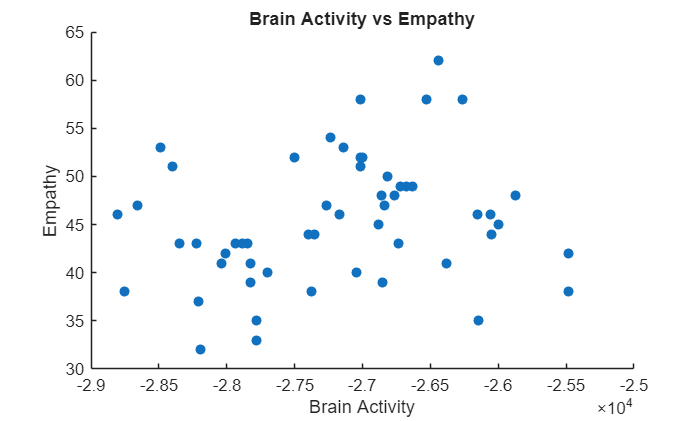


scatter(brain_activity, empathy, 'filled')
xlabel('Brain Activity')
ylabel('Empathy')
title('Brain Activity vs Empathy')


high_empathy = empathy >= 45;
sum(high_empathy)

ans = 28

sum(~high_empathy)

ans = 26

log_model = fitglm(brain_activity, high_empathy, 'Distribution','binomial')

log_model = Generalized linear regression model:
    logit(y) ~ 1 + x1
    Distribution = Binomial

Estimated Coefficients:
                    Estimate         SE        tStat      pValue 
                   __________    __________    ______    ________

    (Intercept)        16.423        9.4803    1.7324    0.083207
    x1             0.00060088    0.00034819    1.7257    0.084393


54 observations, 52 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 3.18, p-value = 0.0743


predict_prob = predict(log_model, brain_activity)

predict_prob =     0.3739
    0.4750
    0.6305
    0.5495
    0.4181
    0.5708
    0.4930
    0.6554
    0.5475
    0.5474
    0.4263
    0.5096
    0.4261
    0.4228
    0.3958


summary(predict_prob)


predict_prob: 54×1 double

    NumMissing           0  
    Min             0.2920  
    Median          0.5359  
    Max             0.7527  
    Mean            0.5185  
    Std             0.1212  




classify_predict = predict_prob >= 0.5

classify_predict = 54×1 logical array
   0
   0
   1
   1
   0
   1
   0
   1
   1
   1
   0
   1
   0
   0
   0



conf_matrix = confusionmat(high_empathy, classify_predict);
accuracy = sum(classify_predict == high_empathy) / length(high_empathy);

disp(conf_matrix)

    18     8
     5    23



disp(['Accuracy = ' num2str(accuracy)])

Accuracy = 0.75926
